# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

## Preprocessing

### Step 1: Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2: Visualize the raw data

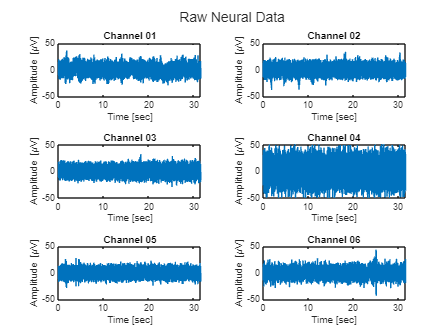

fig_1 = plot_raw_data(training_data);

### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 15; % Change this random value
% Wavelet denoising
wname = 'db4'; % Wavelet type (you can change this if needed)
level = 5; % Decomposition level (adjust as needed)
num_channels = 6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed.

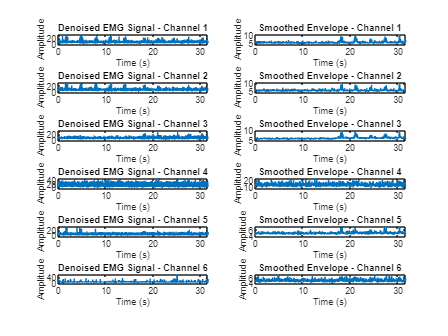

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
temporal_raw = training_data.raw_neural_data;
rectified_data = abs(temporal_raw); % Not used 
[filt_neural_data, ~] = FilterX(b, a, rectified_data, ch_init_conds);
[filt_neural_data2, ~] = FilterX(b, a, temporal_raw, ch_init_conds);
% get signal avg
neural_data_rms = rms(filt_neural_data);
% get signal standard deviation
neural_data_sd = std(filt_neural_data);
% Perform wavelet decomposition
denoised_data = zeros(size(rectified_data));
envelope_data = zeros(size(rectified_data));
for channel = 1:num_channels
    % Compute the envelope of the original signal
    env = abs(hilbert(filt_neural_data2(:, channel)));
    % Perform wavelet decomposition
    % [c, l] = wavedec(filt_neural_data2(:, channel), level, wname);
    [c, l] = wavedec(env, level, wname);

    % Specify a threshold based on a percentage of the maximum coefficients
    threshold_percentage = 10; % Adjust this value as needed
    threshold_value = threshold_percentage / 100 * max(abs(c));

    % Apply thresholding to coefficients
    cnew = wthresh(c, 'h', threshold_value);

    % Reconstruct the denoised signal
    denoised_signal = waverec(cnew, l, wname);

    % Compute the envelope of the denoised signal
    envelope = abs(denoised_signal);

    % Store denoised signal and envelope in matrices
    denoised_data(:, channel) = denoised_signal;
    envelope_data(:, channel) = envelope;
end

% Smooth the envelope using a moving average filter (adjust the window size as needed)
window_size = 1000; % Adjust this to control the smoothing level
smoothed_env_denoised = zeros(size(rectified_data));
for channel = 1:num_channels
    % Smooth the envelope using a moving average filter
    smoothed_env = movmean(envelope_data(:, channel), window_size);
    
    % Store smoothed envelope in the matrix
    smoothed_env_denoised(:, channel) = smoothed_env;
end

smoth_envelop_data_sd = std(smoothed_env_denoised);
denoised_data_sd = std(denoised_data);

% Plot denoised signals and smoothed envelopes for each channel
[num_samples, num_chans] = size(rectified_data);
timestamps = (1:num_samples)/sample_rate;
figure;

for channel = 1:num_channels
    subplot(num_channels, 2, 2 * channel - 1);
    plot(timestamps, denoised_data(:, channel));
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Denoised EMG Signal - Channel ', num2str(channel)]);

    subplot(num_channels, 2, 2 * channel);
    plot(timestamps, smoothed_env_denoised(:, channel));
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Smoothed Envelope - Channel ', num2str(channel)]);
end

#### Step 4: Visualize the filtered data

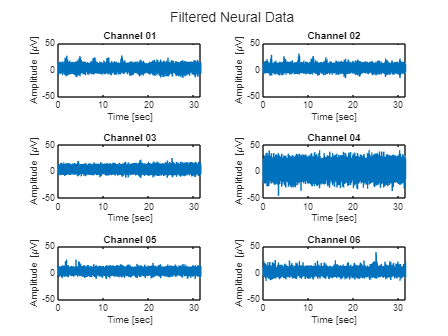

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) in all channels

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been initialized to zero.

% loop over the samples in bin to detect spikes over 2*SD.
spike_locations = zeros(size(filt_neural_data));
spike_locations_denoised = zeros(size(filt_neural_data2));
spike_locations_smooth = zeros(size(filt_neural_data2));
spike_locations_combined = zeros(size(filt_neural_data2));

Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% spike_locations = (randi(7000, size(spike_locations)) == 1); % This code generates random spike locations. Replace with a spike detection algorithm
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = filt_neural_data(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (5.5 * neural_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            sub_spike_array(idx2) = 1;
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = smoothed_env_denoised(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (13.5* smoth_envelop_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_smooth(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array = denoised_data(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array(idx2) > (13.5 * denoised_data_sd(idx1)) 
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_denoised(:, idx1) = sub_spike_array;
end
for idx1 = 1:6
    % Initialize the sub_spike_array
    sub_data_array1 = denoised_data(:, idx1);
    sub_data_array2 = smoothed_env_denoised(:, idx1);
    % Initialize the sub_spike_array
    sub_spike_array = zeros(size(sub_data_array1));

    for idx2 = 1:length(sub_spike_array)
        if sub_data_array1(idx2) > (13 * denoised_data_sd(idx1)) 
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
        if sub_data_array2(idx2) > (13* smoth_envelop_data_sd(idx1))
            % Update the corresponding value in sub_spike_array
            if sub_spike_array(idx2) ~= 1
                if idx1 == 6
                    sub_spike_array(idx2) = 0;
                else
                    sub_spike_array(idx2) = 1;
                end
            end
        end
    end
    % Assign the updated sub_spike_array to spike_locations
    spike_locations_combined(:, idx1) = sub_spike_array;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
spike_locations;

### Step 2: Visualize the spike locations as spike trains in a raster plot

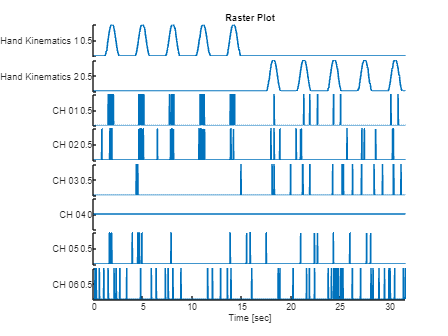

fig_3 = plot_spike_trains(spike_locations, training_data);

% fig_4 = plot_spike_trains(spike_locations_denoised, training_data);
% fig_5 = plot_spike_trains(spike_locations_smooth, training_data);
% fig_6 = plot_spike_trains(spike_locations_combined, training_data);


### Step 3: Plot the action potential waveforms using the spike locations

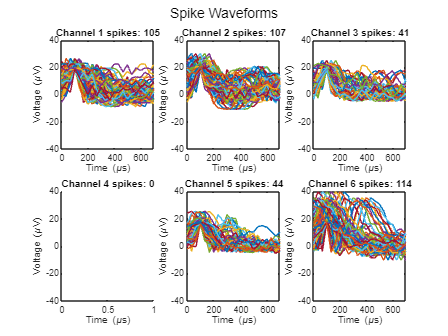

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×105 cell  }
    {1×107 cell  }
    {1×41  cell  }
    {0×0   double}
    {1×44  cell  }
    {1×114 cell  }


Each one of those rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. In order to access the waveforms, you need to specify the channel you want, and then the waveform you are interested in. The waveform itself is a vector containing `22` samples of neural data (`0.1 ms` before and `0.6 ms `after the spike detection).

chan_idx = 1; % random channel
spike_waveforms{chan_idx}

ans = 1×105 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×

waveform_idx = 7; % random waveform
waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data = 22×1 single column vector
    2.9481
   -0.3156
   14.8700
   17.9811
   18.3277
   19.1688
   14.5253
   13.9026
   22.2467
   17.0784


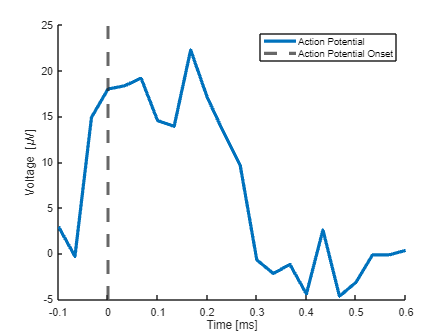

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Onset"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

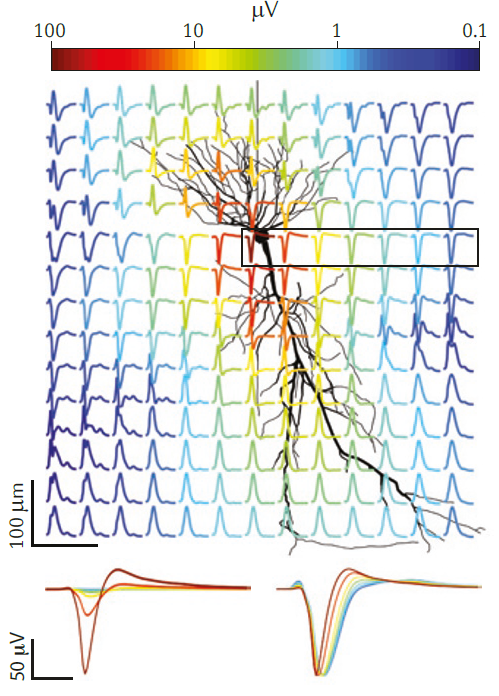

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

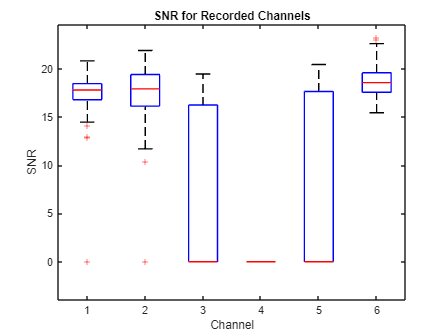

snr_waveforms_b2 = cell(6, 1);
for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    snr_array = cell(1, length(chan_waveforms));
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        % snr_array = cell(1, length(chan_waveforms));
        % Extract the baseline noise 
        noise_baseline = neural_data_sd(chan_idx);
        % Calculate the amplitude of the spike (peak-to-peak)
        spike_amplitude = max(waveform_data) - min(waveform_data);
        % Calculate the SNR for the spike
        snr = 10*log10((spike_amplitude.^2)/(noise_baseline.^2));
        % snr_waveforms(waveform_idx, chan_idx) = snr;
        snr_array{waveform_idx} = snr;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
    snr_waveforms_b2{chan_idx} = snr_array;
end

% Create or open a CSV file to write the SNR values
csv_filename = 'snr_values_b2.csv';
csv_fid = fopen(csv_filename, 'w');

% Write the header row with channel names
for chan_idx = 1:6
    fprintf(csv_fid, 'Channel %d', chan_idx);
    if chan_idx < 6
        fprintf(csv_fid, ',');
    else
        fprintf(csv_fid, '\n');
    end
end

% Write the SNR values to the CSV file by column
for waveform_idx = 1:max(cellfun(@length, snr_waveforms_b2)) % Iterate through waveforms
    for chan_idx = 1:6 % Iterate through channels
        if waveform_idx <= length(snr_waveforms_b2{chan_idx})
            snr_value = snr_waveforms_b2{chan_idx}{waveform_idx};
            fprintf(csv_fid, '%f', snr_value);
        end
        if chan_idx < 6
            fprintf(csv_fid, ',');
        else
            fprintf(csv_fid, '\n');
        end
    end
end

% Close the CSV file
fclose(csv_fid);

% -----------------------------------------
% Load SNR data from the CSV file (if not already loaded)
snr_data = csvread('snr_values_b2.csv', 1, 0); % Skip the header row

% Create a barplot of the SNR values for each channel
figure;
boxplot(snr_data);
xlabel('Channel');
ylabel('SNR');
title('SNR for Recorded Channels');


% Perform pairwise t-tests between channels (adjust alpha as needed)
alpha = 0.05;
channel_labels = {'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4', 'Channel 5', 'Channel 6'};
significant_pairs = [];

for i = 1:size(snr_data, 2)
    for j = i+1:size(snr_data, 2)
        [h, p] = ttest2(snr_data(:, i), snr_data(:, j), 'Alpha', alpha);
        if h
            fprintf('Statistically significant difference between %s and %s (p = %.4f)\n', channel_labels{i}, channel_labels{j}, p);
            significant_pairs = [significant_pairs; i, j];
        end
    end
end

Statistically significant difference between Channel 1 and Channel 3 (p = 0.0000)
Statistically significant difference between Channel 1 and Channel 4 (p = 0.0000)
Statistically significant difference between Channel 1 and Channel 5 (p = 0.0000)
Statistically significant difference between Channel 1 and Channel 6 (p = 0.0000)
Statistically significant difference between Channel 2 and Channel 3 (p = 0.0000)
Statistically significant difference between Channel 2 and Channel 4 (p = 0.0000)
Statistically significant difference between Channel 2 and Channel 5 (p = 0.0000)
Statistically significant difference between Channel 2 and Channel 6 (p = 0.0000)
Statistically significant difference between Channel 3 and Channel 4 (p = 0.0000)
Statistically significant difference between Channel 3 and Channel 6 (p = 0.0000)
Statistically significant difference between Channel 4 and Channel 5 (p = 0.0000)
Statistically significant difference between Channel 4 and Channel 6 (p = 0.0000)
Statistically si


% Display significant channel pairs
if ~isempty(significant_pairs)
    disp('Significant channel pairs:');
    disp(significant_pairs);
else
    disp('No significant differences between channels.');
end

Significant channel pairs:


     1     3
     1     4
     1     5
     1     6
     2     3
     2     4
     2     5
     2     6
     3     4
     3     6
     4     5
     4     6
     5     6



% --------------------------------------------------------------
% % Load SNR data from the CSV file (if not already loaded)
% snr_data = csvread('snr_values_b2.csv', 1, 0); % Skip the header row
% 
% % Get the number of channels
% num_channels = size(snr_data, 2);
% 
% % Initialize a matrix to store p-values
% p_values = zeros(num_channels);
% 
% % Perform Wilcoxon signed-rank test for each pair of channels
% for i = 1:num_channels
%     for j = i+1:num_channels
%         % Perform the Wilcoxon signed-rank test
%         [~, p] = signrank(snr_data(:, i), snr_data(:, j), 'method', 'exact');
% 
%         % Store the p-value in the matrix
%         p_values(i, j) = p;
%     end
% end
% 
% % Display or analyze the p-values as needed
% 
% % Create a heatmap of the p-values
% figure;
% imagesc(p_values);
% colorbar;
% colormap('jet'); % Choose a colormap for better visualization
% xlabel('Channel');
% ylabel('Channel');
% title('Wilcoxon Signed-Rank Test p-values');
% 
% % Add text annotations to highlight significant differences (e.g., p < 0.05)
% significant_p_value = 0.05;
% for i = 1:num_channels
%     for j = i+1:num_channels
%         if p_values(i, j) < significant_p_value
%             text(j, i, '*', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'red', 'FontSize', 14);
%         end
%     end
% end
% 
% % Adjust axis labels and ticks for better readability
% xticks(1:num_channels);
% yticks(1:num_channels);
% xticklabels(1:num_channels);
% yticklabels(1:num_channels);
% axis square;

% Display or save the heatmap as needed


After you've calculated SNRs, make sure to **plot the SNR values** and **run stats**!

## Feature Extraction

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).

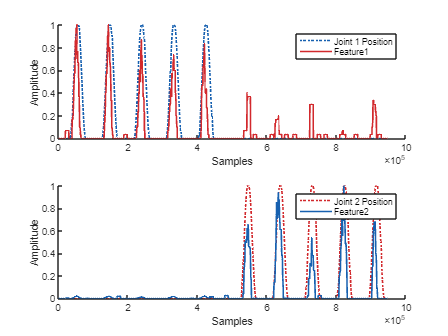

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
selected_features = [1, 2,];

combined_spikes_feature1 = spike_locations(:, 1);
combined_spikes_feature2 = spike_locations_combined(:, 1);

selected_Ch_feature1 = [1, 2];
selected_Ch_feature2 = [1, 2];
% Loop through the selected subarrays and update the combined_spikes_array
for idx = selected_Ch_feature1
    combined_spikes_feature1 = combined_spikes_feature1 | spike_locations(:, idx);
end
% Loop through the selected subarrays and update the combined_spikes_array
for idx = selected_Ch_feature2
    combined_spikes_feature2 = combined_spikes_feature2 | spike_locations_combined(:, idx);
end
kernel_size = 10000; % Adjust the kernel size as needed
smoothing_kernel = ones(1, kernel_size) / kernel_size;
% Specify the indices you want to extract
selected_features1 = [1, 2];
% Normalize the kernel
smoothing_kernel = smoothing_kernel / max(smoothing_kernel);

feature1_b2 = combined_spikes_feature1;
feature1_b2 = conv(feature1_b2, smoothing_kernel, 'same');
feature2_b2 = combined_spikes_feature2;
feature2_b2 = conv(feature2_b2, smoothing_kernel, 'same');

neural_features = spike_locations_combined(:, selected_features1);
neural_features(:, 1) = feature1_b2;
neural_features(:, 2) = feature2_b2;
n_neural_feature1 = normalize(neural_features(:, 1), "range", [0 1]);
n_neural_feature2 = normalize(neural_features(:, 2), "range", [0 1]);
n_neural_features = normalize(neural_features(), "range", [0 1]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

figure
tlo = tiledlayout('flow');
nexttile
hold on
plot(training_data.hand_kinematics(:,1), 'LineStyle',':','Color', "#1761B0", 'LineWidth', 1.5)
plot(normalize(neural_features(:, 1), "range", [0 1]),'LineStyle','-','Color',"#D2292D" ,'LineWidth', 1.5)
hold off
box off
xlabel("Samples")
ylabel("Amplitude")
legend(["Joint 1 Position", "Feature1"])

nexttile
hold on
plot(training_data.hand_kinematics(:,2), 'LineStyle',':','Color', "#D2292D", 'LineWidth', 1.5)
plot(normalize(neural_features(:, 2), "range", [0 1]),'LineStyle','-','Color',"#1761B0" ,'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Amplitude")
legend(["Joint 2 Position", "Feature2"])

% % Test for normality of hand kinematics data (replace with appropriate data)
% [h1, p1] = swtest(training_data.hand_kinematics(:,1));
% disp(['Shapiro-Wilk Test for Hand Kinematics Data: p-value = ', num2str(p1)]);
% 
% % Test for normality of neural features data (replace with appropriate data)
% [h2, p2] = swtest(normalize(neural_features(:, 2), "range", [0 1]));
% disp(['Shapiro-Wilk Test for Neural Features Data: p-value = ', num2str(p2)]);
% -------------------------------------
% % Test for normality of hand kinematics data (replace with appropriate data)
% [h1, p1] = normalitytest(training_data.hand_kinematics(:,1));
% disp(['Normality Test for Hand Kinematics Data: p-value = ', num2str(p1)]);
% 
% % Test for normality of neural features data (replace with appropriate data)
% [h2, p2] = normalize(neural_features(:, 2), "range", [0 1]);
% disp(['Normality Test for Neural Features Data: p-value = ', num2str(p2)]);

% -------------------------------------
% % Perform paired Wilcoxon signed-rank test
% [p, h, stats] = signrank(training_data.hand_kinematics(:,1), normalize(neural_features(:, 2), "range", [0 1]));
% 
% % Display the p-value and test result
% disp(['Paired Wilcoxon Signed-Rank Test p-value: ', num2str(p)]);
% disp(['H0 (null hypothesis) rejected: ', num2str(h)]);
% --------------------------------------
% % Calculate the total number of samples for each condition
% N1 = length(training_data.hand_kinematics(:,1)); % For hand kinematics data
% N2 = length(neural_features(:,1));              % For neural features data
% 
% disp(['Total samples for Hand Kinematics: ', num2str(N1)]);
% disp(['Total samples for Neural Features: ', num2str(N2)]);
% ---------------------------------
% % Define your data arrays (assuming your data is already loaded)
% hand_kinematics = training_data.hand_kinematics(:, 1);
% neural_features = normalize(neural_features(:, 1), "range", [0 1]);

% % Calculate the mid-point to split the data
% midpoint = numel(hand_kinematics) / 2;
% 
% % Split the data into two halves
% hand_kinematics_half1 = hand_kinematics(1:midpoint);
% % hand_kinematics_half2 = hand_kinematics(midpoint+1:end);
% 
% neural_features_half1 = neural_features(1:midpoint);
% % neural_features_half2 = neural_features(midpoint+1:end);
% 
% % Perform normality test on the first half of the data
% r1 = normalitytest(hand_kinematics_half1);
% disp(['Normality Test for Hand Kinematics (First Half): p-value = ', num2str(p1)]);
% 
% r2 = normalitytest(neural_features_half1);
% disp(['Normality Test for Neural Features (First Half): p-value = ', num2str(p2)]);

% Perform normality test on the second half of the data
% [h3, p3] = normalitytest(hand_kinematics_half2);
% disp(['Normality Test for Hand Kinematics (Second Half): p-value = ', num2str(p3)]);
% 
% [h4, p4] = normalitytest(neural_features_half2);
% disp(['Normality Test for Neural Features (Second Half): p-value = ', num2str(p4)]);

% ---------------------------------------------------------
%% Normality Test
hk1 = training_data.hand_kinematics(:,1);
h1 = kstest(hk1)

h1 = logical
   1


[h1,p1,adstat1,cv1] = adtest(hk1);


hk2 = training_data.hand_kinematics(:,2);
h2 = kstest(hk2)

h2 = logical
   1


[h2,p2,adstat2,cv2] = adtest(hk2);


nf1 = n_neural_features(:,1);
h3 = kstest(nf1)

h3 = logical
   1


[h3,p3,adstat3,cv3] = adtest(nf1);


nf2 = n_neural_features(:,2);
h4 = kstest(nf2)

h4 = logical
   1


[h4,p4,adstat4,cv4] = adtest(nf2);

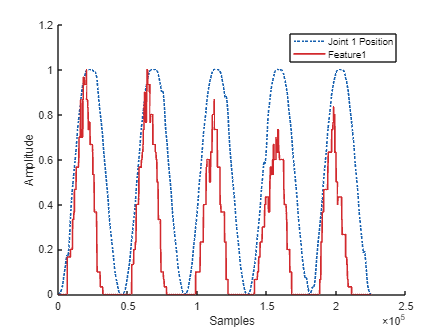


% Select only the elements where training_data.hand_kinematics(:, 1) > 0
positive_hand_kinematics1 = training_data.hand_kinematics(training_data.hand_kinematics(:, 1) > 0, 1);
positive_hand_kinematics2 = training_data.hand_kinematics(training_data.hand_kinematics(:, 2) > 0, 2);
% Corresponding subset of neural_features
positive_neural_features1 = n_neural_features(training_data.hand_kinematics(:, 1) > 0, 1);
positive_neural_features2 = n_neural_features(training_data.hand_kinematics(:, 2) > 0, 2);
% positive_neural_features = n_neural_feature1(training_data.hand_kinematics(:, 1) > 0, 1);
% positive_neural_features = n_neural_feature2(training_data.hand_kinematics(:, 2) > 0, 1);
% Perform normality test on the first half of the data
% r1 = normalitytest(positive_hand_kinematics);
% disp(['Normality Test for Hand Kinematics : p-value = ', num2str(p1)]);
% 
% r2 = normalitytest(positive_neural_features);
% disp(['Normality Test for Neural Features : p-value = ', num2str(p2)]);

figure
tlo = tiledlayout('flow');
nexttile
hold on
plot(positive_hand_kinematics1(:, 1), 'LineStyle',':','Color', "#1761B0", 'LineWidth', 1.5)
plot(positive_neural_features1(:, 1),'LineStyle','-','Color',"#D2292D" ,'LineWidth', 1.5)
hold off
box off
xlabel("Samples")
ylabel("Amplitude")
legend(["Joint 1 Position", "Feature1"])

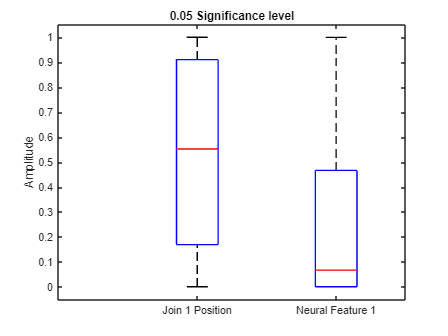

% ------------------------------------------------------------------
% Create a bar plot or box plot
figure;
hold on;

% Box plot (uncomment this section for a box plot)

% boxplot([hk1, nf1], ...
%     'Labels', {'Join 1 Position', 'Neural Feature 1'});
boxplot([positive_hand_kinematics1(:, 1), positive_neural_features1(:, 1)], ...
    'Labels', {'Join 1 Position', 'Neural Feature 1'});
ylabel('Amplitude');
title('0.05 Significance level');
hold off

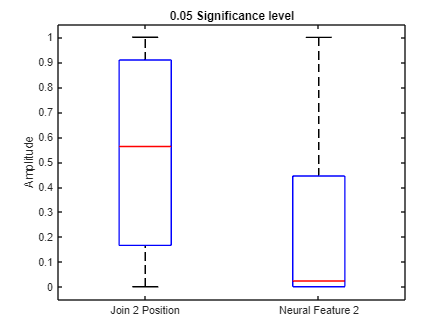

% boxplot([hk2, nf2], ...
%     'Labels', {'Join 1 Position', 'Neural Feature 1'});
boxplot([positive_hand_kinematics2(:, 1), positive_neural_features2(:, 1)], ...
    'Labels', {'Join 2 Position', 'Neural Feature 2'});
ylabel('Amplitude');
title('0.05 Significance level');
hold off

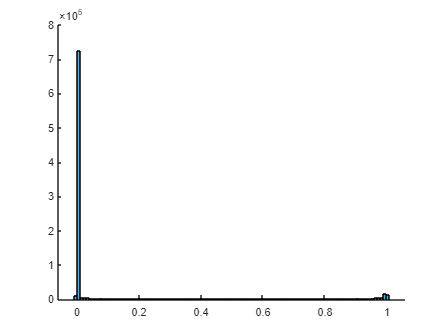


figure;
hold on
histogram(hk1);
hold off

% ------------------------------------------------------------------
% % Assuming neural_features is a 1,000,000-long array
% % Partition data into first and second halves
% half_length = length(neural_features(:, 1)) / 2;
% neural_first_half = neural_features(1:half_length, 1);
% neural_second_half = neural_features(half_length + 1:end, 2);

% % Define your performance metrics (modify this part)
% % Calculate performance metrics for the first neural feature
% metric1_first_half = calculate_metric(neural_first_half);
% metric1_second_half = calculate_metric(neural_second_half);
% 
% % Calculate performance metrics for the second neural feature
% metric2_first_half = calculate_metric(neural_first_half);
% metric2_second_half = calculate_metric(neural_second_half);
% 
% % Perform statistical tests (modify this part)
% % For example, perform a t-test to compare metrics between neural features
% [h1, p1] = ttest2(metric1_first_half, metric1_second_half);
% [h2, p2] = ttest2(metric2_first_half, metric2_second_half);
% 
% % Create a barplot or boxplot (modify this part)
% % If you have multiple metrics, you can create multi-panel figures
% figure;
% 
% % Create subplots for each metric
% subplot(2, 1, 1); % Subplot 1 for Metric 1
% % Create a barplot or boxplot for Metric 1
% % Add title and labels
% title('Metric 1');
% ylabel('Metric Value');
% set(gca, 'XTickLabel', {'Neural Feature 1', 'Neural Feature 2'});
% legend('p-value < 0.05', 'p-value >= 0.05');

% subplot(2, 1, 2); % Subplot 2 for Metric 2
% % Create a barplot or boxplot for Metric 2
% % Add title and labels
% title('Metric 2');
% ylabel('Metric Value');
% set(gca, 'XTickLabel', {'Neural Feature 1', 'Neural Feature 2'});
% legend('p-value < 0.05', 'p-value >= 0.05');

% Save or display the figure
% saveas(gcf, 'performance_metrics_comparison.png'); % If you want to save the figure
% ---------------------------------------------
nb2_N_F1 = normalize(neural_features(:, 1));
Training_JP1 = training_data.hand_kinematics(:,1);

nb2_N_F2 = normalize(neural_features(:, 2));
Training_JP2 = training_data.hand_kinematics(:,2);

nb2NF1_TJP1 = signrank(nb2_N_F1, Training_JP1)

nb2NF1_TJP1 = 0


nb2NF2_TJP2 = signrank(nb2_N_F2, Training_JP2)

nb2NF2_TJP2 = 0


save("results\features", "neural_features")

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function metric_value = calculate_metric(neural_data)
    % Your custom metric calculation logic
    % For example, calculate the mean value of the input data
    % metric_value = mean(neural_data);
    metric_value = kstest(neural_data);
end

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end

function plot_spike_trains1(fig_handle, spike_locations, training_data)
    % Use the provided figure handle
    figure(fig_handle);
    
    % Rest of your existing code
    t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
    plot(t, [training_data.hand_kinematics, spike_locations], 'LineWidth', 1.5);
    xlabel("Time [sec]");
    title("Raster Plot");
    legend("Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06");
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan) ' spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end